T = 10; dt = 0.001;
t = -T/2 : dt : T/2;

square_wave = zeros(size(t));
square_wave(abs(t) <= 0.5) = 1;

V = 1/dt; dv = 1/T;
v = -V/2 : dv : V/2;

fourier_domain = sinc(v);

numerical_fourier = zeros(size(v));
for k = 1 : length(t)
    numerical_fourier(k) = trapz(t, square_wave .* exp(-2*pi*1i .* v(k) .* t));
end

numerical_square_wave = zeros(size(t));
for k = 1 : length(v)
    numerical_square_wave(k) = trapz(v, numerical_fourier .* exp(2*pi*1i .* v .* t(k)));
end

dft_fourier = fftshift(fft(square_wave)) ./ sqrt(length(t));
dft_square_wave = ifft(ifftshift(dft_fourier)) .* sqrt(length(v));

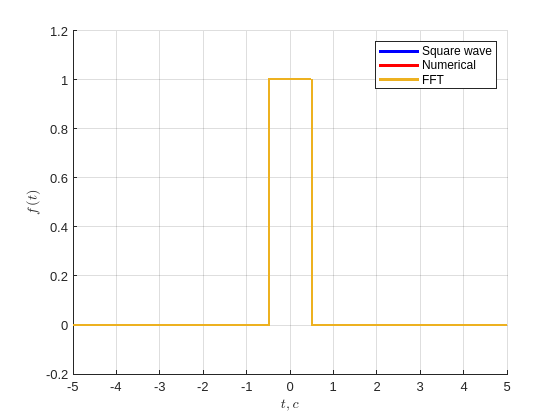

figure;
hold on;
plot(t, square_wave, 'b', 'LineWidth', 2);
plot(t, real(numerical_square_wave), 'r', 'LineWidth', 2);
plot(t, real(dft_square_wave), 'LineWidth', 2);
hold off;

ylabel({"$f(t)$"}, 'Interpreter', 'latex');
xlabel({"$t, c$"}, 'Interpreter', 'latex');
legend({"Square wave", "Numerical", "FFT"});
grid on;

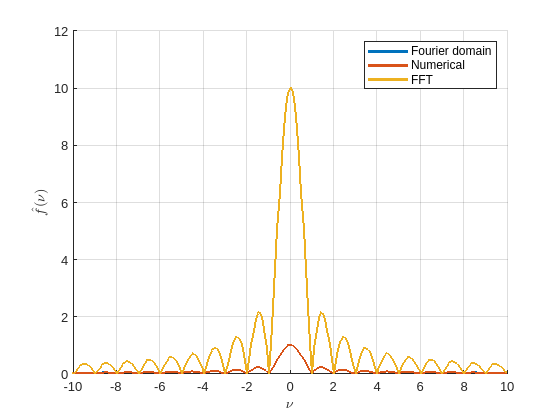

figure;
hold on;
plot(v, abs(fourier_domain), 'LineWidth', 2);
plot(v, abs(numerical_fourier), 'LineWidth', 2);
plot(v, abs(dft_fourier), 'LineWidth', 2);
hold off;

xlim([-10, 10]);
ylabel({"$\hat{f}(\nu)$"}, 'Interpreter', 'latex');
xlabel({"$\nu$"}, 'Interpreter', 'latex');
legend({"Fourier domain", "Numerical", "FFT"});
grid on;